361.x=[4 3 7 -9 1 0 0]

- 求x的快速傅立業轉換。             **(5分)**

- 對x做8點的快速傅立業轉換。    **(5分)**

- 對x做6點的快速傅立業轉換。    **(5分)**

- 若x為多維度矩陣(請自行定義)，觀察fft(x)變化並描述與向量之差異為何。    **(5分)**

x=[4 3 7 -9 1 0 0]

x =      4     3     7    -9     1     0     0


x1=fft(x)

x1 =    6.0000 + 0.0000i  11.5206 - 4.8312i  -7.9623 - 7.7059i   7.4417 +13.9204i   7.4417 -13.9204i  -7.9623 + 7.7059i  11.5206 + 4.8312i


x2=fft(x,8)

x2 =    6.0000 + 0.0000i  11.4853 - 2.7574i  -2.0000 -12.0000i  -5.4853 +11.2426i  18.0000 + 0.0000i  -5.4853 -11.2426i  -2.0000 +12.0000i  11.4853 + 2.7574i


x3=fft(x,6)

x3 =    6.0000 + 0.0000i  10.5000 - 7.7942i -10.5000 + 2.5981i  18.0000 + 0.0000i -10.5000 - 2.5981i  10.5000 + 7.7942i


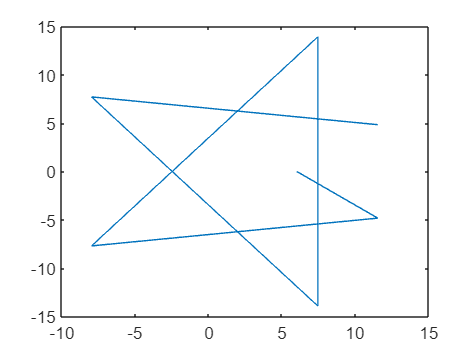

plot(x1)


y=[4 3 7 -9 ; 1 0 0 0]

y =      4     3     7    -9
     1     0     0     0


x1=fft(y,8,2)

x1 =    5.0000 + 0.0000i  12.4853 - 2.7574i  -3.0000 -12.0000i  -4.4853 +11.2426i  17.0000 + 0.0000i  -4.4853 -11.2426i  -3.0000 +12.0000i  12.4853 + 2.7574i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


x2=fft(y,8)

x2 =    5.0000 + 0.0000i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i
   4.7071 - 0.7071i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i
   4.0000 - 1.0000i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i
   3.2929 - 0.7071i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i
   3.0000 + 0.0000i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i
   3.2929 + 0.7071i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i
   4.0000 + 1.0000i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i
   4.7071 + 0.7071i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i


x3=fft(y,6)

x3 =    5.0000 + 0.0000i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i
   4.5000 - 0.8660i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i
   3.5000 - 0.8660i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i
   3.0000 + 0.0000i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i
   3.5000 + 0.8660i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i
   4.5000 + 0.8660i   3.0000 + 0.0000i   7.0000 + 0.0000i  -9.0000 + 0.0000i


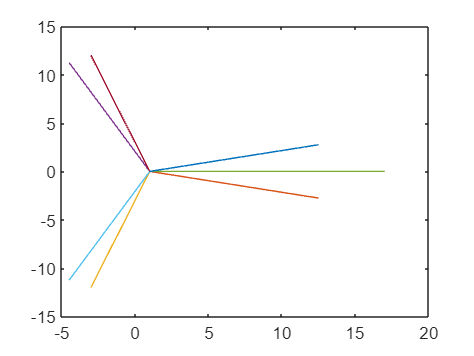

plot(x1)


%%向量是每個連在一起，下面的那張圖變成每列一樣的連在一起



2.請參考講義FFT的範例 ，畫出訊號經過FFT處理前與處理後的圖

- 訊號源為0.5*sin(2*pi*50*time) + sin(2*pi*120*time)     **(10分)**

- 取樣頻率為1000                                                            **(10分)**

%原本的
freq=(-N/2:N/2-1)

freq =   -128  -127  -126  -125  -124  -123  -122  -121  -120  -119  -118  -117  -116  -115  -114  -113  -112  -111  -110  -109  -108  -107  -106  -105  -104  -103  -102  -101  -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79


N=256

N = 256

fs=8000

fs = 8000

freqStep=fs/N

freqStep = 31.2500

time=(0:N-1)/fs

time =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0022    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0032    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


f=10*freqStep

f = 312.5000

y=cos(2*pi*f*time) 

y =     1.0000    0.9700    0.8819    0.7410    0.5556    0.3369    0.0980   -0.1467   -0.3827   -0.5957   -0.7730   -0.9040   -0.9808   -0.9988   -0.9569   -0.8577   -0.7071   -0.5141   -0.2903   -0.0491    0.1951    0.4276    0.6344    0.8032    0.9239    0.9892    0.9952    0.9415    0.8315    0.6716    0.4714    0.2430    0.0000   -0.2430   -0.4714   -0.6716   -0.8315   -0.9415   -0.9952   -0.9892   -0.9239   -0.8032   -0.6344   -0.4276   -0.1951    0.0491    0.2903    0.5141    0.7071    0.8577


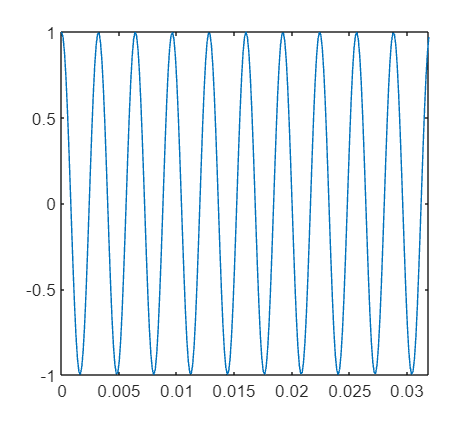

plot(time,y)

Y=fft(y)

Y = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   1.2800 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i


Y=fftshift(Y)

Y = 1.0e+02 *

  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i


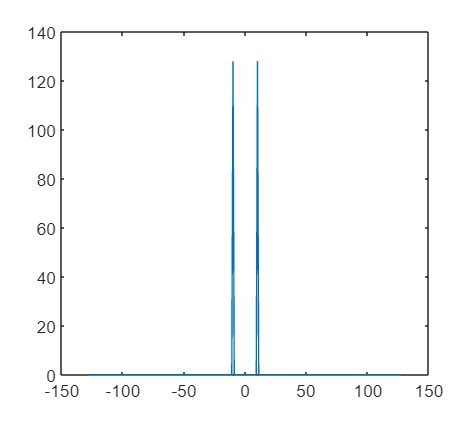

plot(freq,abs(Y))


%改變訊號源
N=256

N = 256

fs=8000

fs = 8000

freqStep=fs/N

freqStep = 31.2500

time=(0:N-1)/fs

time =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0022    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0032    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


y=0.5*sin(2*pi*50*time)+sin(2*pi*120*time) 

y =          0    0.1137    0.2266    0.3378    0.4463    0.5515    0.6525    0.7486    0.8391    0.9232    1.0004    1.0701    1.1318    1.1852    1.2298    1.2655    1.2919    1.3091    1.3168    1.3153    1.3046    1.2849    1.2565    1.2197    1.1750    1.1228    1.0637    0.9983    0.9273    0.8512    0.7710    0.6872    0.6009    0.5126    0.4234    0.3340    0.2452    0.1578    0.0727   -0.0094   -0.0878   -0.1617   -0.2305   -0.2936   -0.3505   -0.4006   -0.4436   -0.4791   -0.5068   -0.5265


plot(time,y)
freq=(-N/2:N/2-1)

freq =   -128  -127  -126  -125  -124  -123  -122  -121  -120  -119  -118  -117  -116  -115  -114  -113  -112  -111  -110  -109  -108  -107  -106  -105  -104  -103  -102  -101  -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79


Y=fft(y)

Y = 1.0e+02 *

   0.2852 + 0.0000i   0.4364 + 0.1018i  -0.3363 - 0.1022i   0.0405 + 0.1239i  -0.6172 - 1.1325i  -0.0915 - 0.1943i  -0.0462 - 0.1185i  -0.0283 - 0.0882i  -0.0187 - 0.0713i  -0.0129 - 0.0603i  -0.0089 - 0.0524i  -0.0062 - 0.0465i  -0.0042 - 0.0418i  -0.0026 - 0.0380i  -0.0014 - 0.0349i  -0.0005 - 0.0323i   0.0003 - 0.0300i   0.0009 - 0.0280i   0.0014 - 0.0263i   0.0019 - 0.0248i   0.0023 - 0.0234i   0.0026 - 0.0222i   0.0029 - 0.0211i   0.0031 - 0.0201i   0.0033 - 0.0192i   0.0035 - 0.0183i   0.0036 - 0.0175i   0.0038 - 0.0168i   0.0039 - 0.0162i   0.0040 - 0.0155i   0.0041 - 0.0150i   0.0042 - 0.0144i   0.0043 - 0.0139i   0.0044 - 0.0134i   0.0045 - 0.0130i   0.0045 - 0.0126i   0.0046 - 0.0121i   0.0047 - 0.0118i   0.0047 - 0.0114i   0.0048 - 0.0111i   0.0048 - 0.0107i   0.0048 - 0.0104i   0.0049 - 0.0101i   0.0049 - 0.0098i   0.0049 - 0.0096i   0.0050 - 0.0093i   0.0050 - 0.0090i   0.0050 - 0.0088i   0.0050 - 0.0086i   0.0051 - 0.0083i


Y=fftshift(Y)

Y = 1.0e+02 *

   0.0055 + 0.0000i   0.0055 + 0.0001i   0.0055 + 0.0001i   0.0055 + 0.0002i   0.0055 + 0.0003i   0.0055 + 0.0004i   0.0055 + 0.0004i   0.0055 + 0.0005i   0.0055 + 0.0006i   0.0055 + 0.0006i   0.0055 + 0.0007i   0.0055 + 0.0008i   0.0055 + 0.0008i   0.0055 + 0.0009i   0.0055 + 0.0010i   0.0055 + 0.0011i   0.0055 + 0.0011i   0.0055 + 0.0012i   0.0055 + 0.0013i   0.0055 + 0.0014i   0.0055 + 0.0014i   0.0055 + 0.0015i   0.0055 + 0.0016i   0.0055 + 0.0017i   0.0055 + 0.0017i   0.0055 + 0.0018i   0.0055 + 0.0019i   0.0055 + 0.0020i   0.0055 + 0.0020i   0.0055 + 0.0021i   0.0055 + 0.0022i   0.0055 + 0.0023i   0.0055 + 0.0024i   0.0055 + 0.0024i   0.0055 + 0.0025i   0.0055 + 0.0026i   0.0054 + 0.0027i   0.0054 + 0.0028i   0.0054 + 0.0029i   0.0054 + 0.0030i   0.0054 + 0.0030i   0.0054 + 0.0031i   0.0054 + 0.0032i   0.0054 + 0.0033i   0.0054 + 0.0034i   0.0054 + 0.0035i   0.0054 + 0.0036i   0.0054 + 0.0037i   0.0054 + 0.0038i   0.0054 + 0.0039i


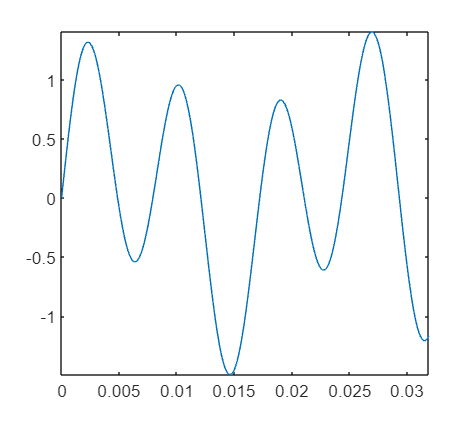

axis("tight")

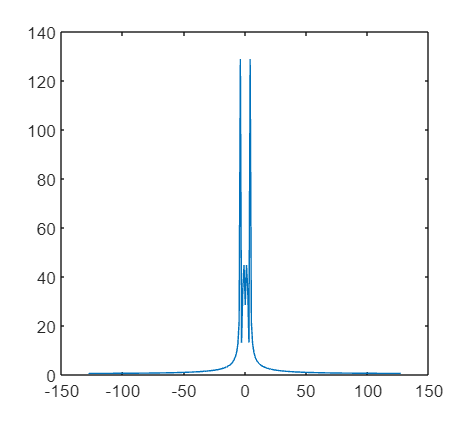

plot(freq,abs(Y))



%改變取樣頻率
N=256

N = 256

fs=1000

fs = 1000

freqStep=fs/N

freqStep = 3.9063

time=(0:N-1)/fs

time =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


y=0.5*sin(2*pi*50*time)+sin(2*pi*120*time) 

y =          0    0.8391    1.2919    1.1750    0.6009   -0.0878   -0.5068   -0.4398    0.0452    0.6363    0.9511    0.7503    0.0742   -0.7726   -1.3804   -1.4511   -0.9573   -0.1558    0.5504    0.8278    0.5878    0.0292   -0.4766   -0.5935   -0.2090    0.5000    1.1601    1.4025    1.0644    0.2798   -0.5878   -1.1368   -1.1382   -0.6532    0.0062    0.4511    0.4293   -0.0364   -0.6620   -1.0593   -0.9511   -0.3272    0.5426    1.2488    1.4578    1.0878    0.3502   -0.3660   -0.7041   -0.5300


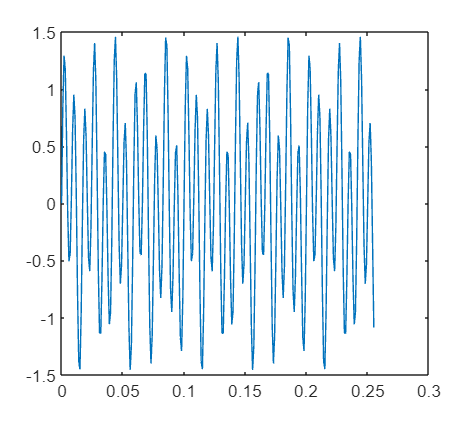

plot(time,y)

Y=fft(y)

Y =    3.3191 + 0.0000i   3.3275 + 0.1645i   3.3533 + 0.3337i   3.3981 + 0.5130i   3.4652 + 0.7090i   3.5599 + 0.9308i   3.6911 + 1.1921i   3.8744 + 1.5154i   4.1384 + 1.9408i   4.5420 + 2.5499i   5.2281 + 3.5397i   6.6565 + 5.5435i  11.5842 +12.3557i -32.3562 -48.1012i  -2.9710 - 7.6422i  -0.2343 - 3.8708i   0.8498 - 2.3837i   1.4741 - 1.5405i   1.9168 - 0.9600i   2.2801 - 0.5041i   2.6139 - 0.1075i   2.9495 + 0.2681i   3.3133 + 0.6513i   3.7333 + 1.0697i   4.2475 + 1.5575i   4.9151 + 2.1656i   5.8422 + 2.9830i   7.2453 + 4.1899i   9.6569 + 6.2274i  14.8447 +10.5586i  34.3917 +26.7662i -85.5819 -72.4501i -18.0798 -16.5749i  -9.7828 - 9.6802i  -6.5412 - 6.9692i  -4.8122 - 5.5110i  -3.7369 - 4.5948i  -3.0033 - 3.9624i  -2.4708 - 3.4975i  -2.0668 - 3.1398i  -1.7499 - 2.8550i  -1.4946 - 2.6220i  -1.2847 - 2.4273i  -1.1092 - 2.2617i  -0.9602 - 2.1188i  -0.8323 - 1.9939i  -0.7214 - 1.8836i  -0.6243 - 1.7852i  -0.5386 - 1.6968i  -0.4626 - 1.6168i


Y=fftshift(Y)

Y =    0.4665 + 0.0000i   0.4664 + 0.0100i   0.4663 + 0.0199i   0.4661 + 0.0299i   0.4658 + 0.0399i   0.4654 + 0.0499i   0.4649 + 0.0599i   0.4643 + 0.0700i   0.4636 + 0.0801i   0.4628 + 0.0902i   0.4619 + 0.1003i   0.4609 + 0.1105i   0.4599 + 0.1207i   0.4587 + 0.1310i   0.4574 + 0.1414i   0.4560 + 0.1518i   0.4546 + 0.1622i   0.4530 + 0.1728i   0.4513 + 0.1834i   0.4494 + 0.1941i   0.4475 + 0.2049i   0.4454 + 0.2157i   0.4433 + 0.2267i   0.4410 + 0.2378i   0.4385 + 0.2490i   0.4359 + 0.2603i   0.4332 + 0.2717i   0.4304 + 0.2832i   0.4274 + 0.2949i   0.4242 + 0.3068i   0.4209 + 0.3188i   0.4174 + 0.3309i   0.4137 + 0.3432i   0.4099 + 0.3557i   0.4058 + 0.3684i   0.4016 + 0.3813i   0.3971 + 0.3944i   0.3925 + 0.4077i   0.3876 + 0.4213i   0.3825 + 0.4351i   0.3771 + 0.4491i   0.3715 + 0.4635i   0.3655 + 0.4781i   0.3593 + 0.4930i   0.3528 + 0.5083i   0.3460 + 0.5239i   0.3388 + 0.5398i   0.3312 + 0.5561i   0.3233 + 0.5729i   0.3149 + 0.5901i


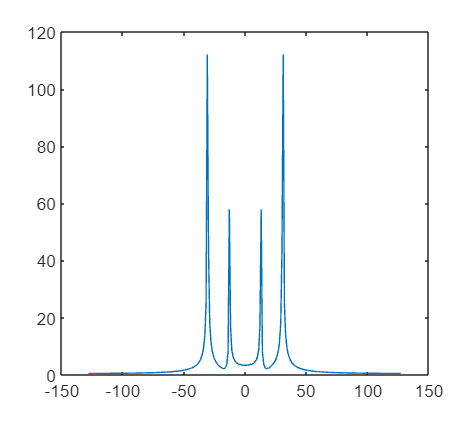

plot(freq,abs(Y))

3.讀取影像檔L5_1.bmp

- 此圖形經過直方圖等化處理並比較差異。               **(10分)**

- 將處理前後的灰階直方圖畫出並比較差異。               **10分)**

image_1=imread("l5_1.bmp")

image_1 = 511×512 uint8 matrix
    94    91    94    96    99    96    96    96    94    94    94    94    94    94    93    91    88    86    90    90    90    91    91    90    93    95    99    95    93    91    90    91    93    91    91    91    90    90    91    91    90    91    90    93    94    91    90    90    88    88
    95    96    96    95    99    99    99    96    96    94    94    94    94    94    91    90    90    94    94    94    94    93    94    90    94    94    91    91    91    91    90    91    91    90    91    91    90    90    91    90    94    93    96    96    94    90    91    91    94    94
    93    94    93    93    94    96    96    96    95    96    94    94    94    93    94    94    91    93    94    94    94    93    94    94    93    94    94    90    91    91    91    93    94    93    94    91    91    91    91    91    94    94    94    94    90    91    90    91    90    90
    90    93    94    93    90    94    93    96    95    96    96

image_2=histeq(image_1)%%值方圖等化處理

image_2 = 511×512 uint8 matrix
   231   223   231   235   239   235   235   235   231   231   231   231   231   231   227   223   202   198   219   219   219   223   223   219   227   235   239   235   227   223   219   223   227   223   223   223   219   219   223   223   219   223   219   227   231   223   219   219   202   202
   235   235   235   235   239   239   239   235   235   231   231   231   231   231   223   219   219   231   231   231   231   227   231   219   231   231   223   223   223   223   219   223   223   219   223   223   219   219   223   219   231   227   235   235   231   219   223   223   231   231
   227   231   227   227   231   235   235   235   235   235   231   231   231   227   231   231   223   227   231   231   231   227   231   231   227   231   231   219   223   223   223   227   231   227   231   223   223   223   223   223   231   231   231   231   219   223   219   223   219   219
   219   227   231   227   219   231   227   235   235   235   235

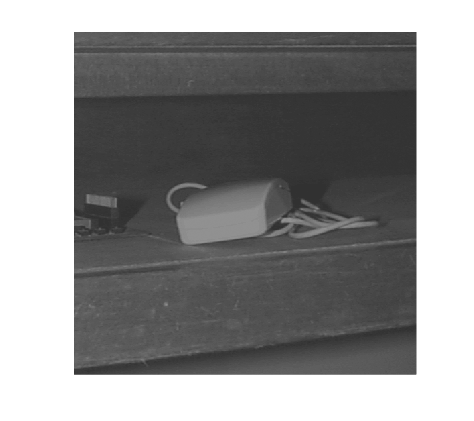


%%show出圖
imshow(image_1)

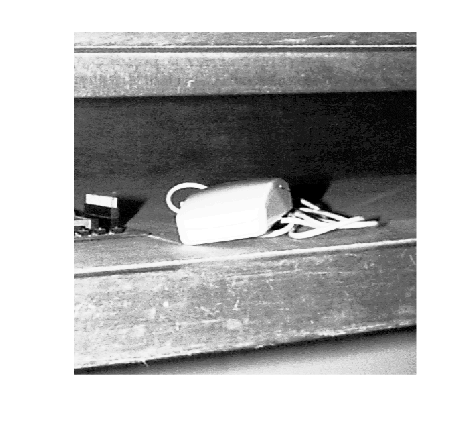

imshow(image_2)

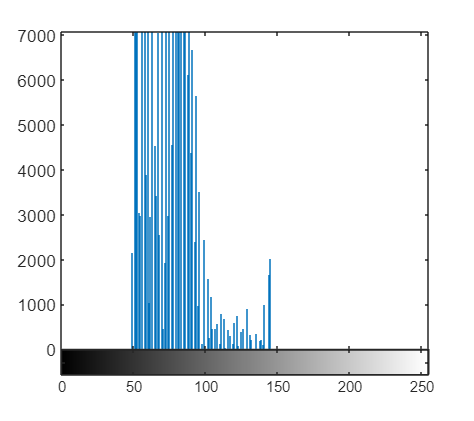


%%秀出直方圖
imhist(image_1)

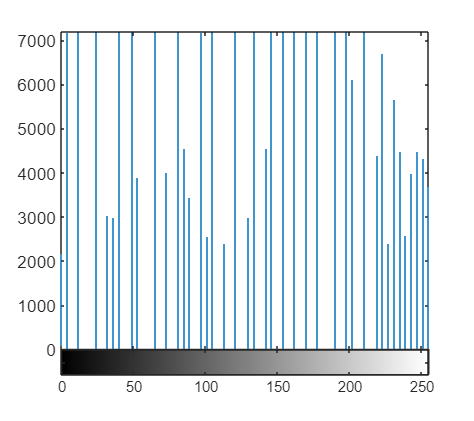

imhist(image_2)

4.讀取影像檔L5_2.bmp

- 參考講義，將胡椒鹽式的雜訊加入原影像中並顯示出來。     **(6分)** 

- 以低通濾波器處理，顯示結果。                                             **(6分)**

- 以中值濾波器處理，顯示結果並與低通進行比較。                **(8分)** 

image_3=imread("l5_2.bmp")

image_3 = 554×500 uint8 matrix
   202   201   201   201   202   202   204   204   204   205   203   202   202   201   202   201   200   198   198   199   200   200   200   199   198   200   201   201   201   197   196   197   200   199   199   199   199   202   202   199   201   201   201   200   198   195   195   195   198   198
   199   198   199   201   202   202   202   202   204   204   204   202   200   201   201   200   200   200   201   202   201   198   198   196   198   199   198   199   201   200   199   197   197   200   201   201   200   199   200   202   204   202   201   200   199   198   196   195   198   198
   198   198   198   200   202   202   202   202   204   203   202   200   199   196   198   200   201   200   201   202   202   200   198   198   199   198   199   201   201   201   200   199   199   200   200   200   200   197   198   199   200   199   200   199   198   198   196   196   199   197
   200   201   200   200   201   202   202   203   204   204   203

image_noisy=imnoise(image_3,"salt & pepper",0.06)

image_noisy = 554×500 uint8 matrix
   202   201   201   201   202   202   204   204   204   205   203   202   202   201   202   201   200   198   255   199     0   200   200   199   198   200   201   201   201   197   196   197   255   199   199   199   199   202   202   199   201   201   201   200   198   195   195   195   198   198
   199     0   199   201   202   202   202   202   204   204   204   202     0   201   201   200   200   200   201   202   201   198   198   196   198   199   198   199   201   200   199   197   197   200   201   201   200   199   200   202   204   202   201   200   199   198   196   195   198   198
   198   198   198   200   202   202   202   202   204   203   202   200   199   196   198   200   201   200     0   202   202   200   198   198   199   255   199   201   201   201   200   199   199   200   200   200   200   197   198   199   200   199   200   199   198   255   196   196   199   197
   200   201   200   200   201   202   202   203   204   204  

image_2_noisy=double(image_noisy)/255

image_2_noisy =     0.7922    0.7882    0.7882    0.7882    0.7922    0.7922    0.8000    0.8000    0.8000    0.8039    0.7961    0.7922    0.7922    0.7882    0.7922    0.7882    0.7843    0.7765    1.0000    0.7804         0    0.7843    0.7843    0.7804    0.7765    0.7843    0.7882    0.7882    0.7882    0.7725    0.7686    0.7725    1.0000    0.7804    0.7804    0.7804    0.7804    0.7922    0.7922    0.7804    0.7882    0.7882    0.7882    0.7843    0.7765    0.7647    0.7647    0.7647    0.7765    0.7765
    0.7804         0    0.7804    0.7882    0.7922    0.7922    0.7922    0.7922    0.8000    0.8000    0.8000    0.7922         0    0.7882    0.7882    0.7843    0.7843    0.7843    0.7882    0.7922    0.7882    0.7765    0.7765    0.7686    0.7765    0.7804    0.7765    0.7804    0.7882    0.7843    0.7804    0.7725    0.7725    0.7843    0.7882    0.7882    0.7843    0.7804    0.7843    0.7922    0.8000    0.7922    0.7882    0.7843    0.7804    0.7765    0.7686    0.7647   

h=[1/9 1/9 1/9; 1/9 1/9 1/9 ;1/9 1/9 1/9]

h =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


image_low=filter2(h,image_2_noisy)

image_low =     0.2623    0.4366    0.4370    0.5255    0.5272    0.5290    0.5298    0.5316    0.5329    0.5333    0.5316    0.4414    0.4392    0.4388    0.5255    0.5246    0.5224    0.5464    0.5468    0.4610    0.4357    0.4344    0.5190    0.5181    0.5185    0.5203    0.5220    0.5233    0.5224    0.5203    0.5168    0.5407    0.5425    0.5451    0.5224    0.5224    0.5229    0.5237    0.5246    0.5264    0.5268    0.5272    0.5251    0.5224    0.5185    0.5146    0.5115    0.5129    0.5150    0.5194
    0.4349    0.6954    0.6967    0.7869    0.7904    0.7930    0.7939    0.7965    0.7983    0.7987    0.7952    0.7033    0.6985    0.6972    0.7843    0.7856    0.7843    0.7211    0.7220    0.6370    0.6989    0.6959    0.7786    0.7773    0.8026    0.8048    0.8074    0.7852    0.7852    0.7826    0.7782    0.8013    0.8031    0.8061    0.7839    0.7839    0.7830    0.7830    0.7834    0.7865    0.7874    0.7882    0.7856    0.7826    0.8026    0.7974    0.7935    0.7704    0.7

image_med=medfilt2(image_noisy,[3 3])

image_med = 554×500 uint8 matrix
     0   199   199   201   201   202   202   202   204   204   202   202   201   201   201   200   200   200   199   199   198   198   198   198   198   198   199   199   199   197   197   197   197   199   199   199   199   199   199   200   201   201   200   199   198   195   195   195   195   198
   198   199   200   201   202   202   202   204   204   204   203   202   201   201   201   200   200   200   200   201   200   200   198   198   199   199   200   201   201   200   199   199   199   200   200   200   200   200   199   200   201   201   200   200   199   198   196   196   198   198
   198   199   200   200   202   202   202   202   204   204   203   201   200   198   199   200   200   200   201   201   201   199   198   198   198   198   199   201   201   201   200   199   199   200   200   200   200   200   199   200   200   200   200   199   198   198   197   196   197   198
   198   200   200   200   201   202   202   204   204   203   2

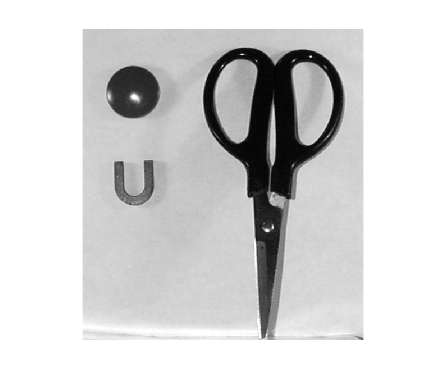


imshow(image_3)

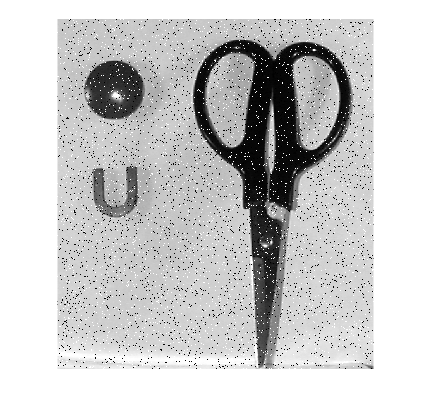

figure,imshow(image_noisy)

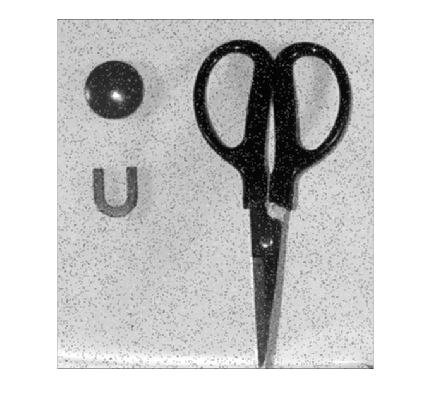

figure,imshow(image_low)

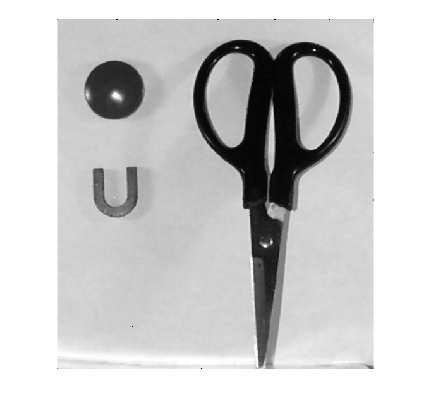

figure,imshow(image_med)

%%中濾通波比較乾淨


5.重做Q4低通濾波器處理

- 將遮罩大小改為5*5，並與遮罩大小為3*3的結果做比較。               **(10分)**

- 將所加雜訊改為高斯雜訊並與胡椒鹽式雜訊的結果做比較。            **(10分)**

image_3=imread("l5_2.bmp")

image_3 = 554×500 uint8 matrix
   202   201   201   201   202   202   204   204   204   205   203   202   202   201   202   201   200   198   198   199   200   200   200   199   198   200   201   201   201   197   196   197   200   199   199   199   199   202   202   199   201   201   201   200   198   195   195   195   198   198
   199   198   199   201   202   202   202   202   204   204   204   202   200   201   201   200   200   200   201   202   201   198   198   196   198   199   198   199   201   200   199   197   197   200   201   201   200   199   200   202   204   202   201   200   199   198   196   195   198   198
   198   198   198   200   202   202   202   202   204   203   202   200   199   196   198   200   201   200   201   202   202   200   198   198   199   198   199   201   201   201   200   199   199   200   200   200   200   197   198   199   200   199   200   199   198   198   196   196   199   197
   200   201   200   200   201   202   202   203   204   204   203

image_noisy=imnoise(image_3,"salt & pepper",0.06)

image_noisy = 554×500 uint8 matrix
   202   201   201   201   202   202   204   204   204   205   203   202   202   201   202   201   200   198   198   199   200   200   200   199   198   200   201   201   201   197   196   197   200   199   199   199   199   202   202   199   201   201   201     0   198   195   195   195   255   198
   199   198   199   201   202   202   202   202   204   204   204   202   200   201   201   200   200   200   201   202   201   198   198   196   198   199   198     0   201   200   199   197   197   200   201     0   200   199   200   202   204   202   201   200   199   198   196   195   198   198
   198   198   198   200   202   202   202   202   204   203   202   200     0   196   198   200   201   200   201   202   202   200   198   198   199     0   199   201   201   201   200   199   199   200   200   200   200   197   198   199   200   199     0   199   198   198   196   196   199   197
   200   201   200   200   201   202   202   203   204   204  

image_2_noisy=double(image_noisy)/255

image_2_noisy =     0.7922    0.7882    0.7882    0.7882    0.7922    0.7922    0.8000    0.8000    0.8000    0.8039    0.7961    0.7922    0.7922    0.7882    0.7922    0.7882    0.7843    0.7765    0.7765    0.7804    0.7843    0.7843    0.7843    0.7804    0.7765    0.7843    0.7882    0.7882    0.7882    0.7725    0.7686    0.7725    0.7843    0.7804    0.7804    0.7804    0.7804    0.7922    0.7922    0.7804    0.7882    0.7882    0.7882         0    0.7765    0.7647    0.7647    0.7647    1.0000    0.7765
    0.7804    0.7765    0.7804    0.7882    0.7922    0.7922    0.7922    0.7922    0.8000    0.8000    0.8000    0.7922    0.7843    0.7882    0.7882    0.7843    0.7843    0.7843    0.7882    0.7922    0.7882    0.7765    0.7765    0.7686    0.7765    0.7804    0.7765         0    0.7882    0.7843    0.7804    0.7725    0.7725    0.7843    0.7882         0    0.7843    0.7804    0.7843    0.7922    0.8000    0.7922    0.7882    0.7843    0.7804    0.7765    0.7686    0.7647   

h=[1/9 1/9 1/9; 1/9 1/9 1/9 ;1/9 1/9 1/9]

h =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


h1=[1/25 1/25 1/25 1/25 1/25;1/25 1/25 1/25 1/25 1/25; 1/25 1/25 1/25 1/25 1/25; 1/25 1/25 1/25 1/25 1/25; 1/25 1/25 1/25 1/25 1/25;]

h1 =     0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400


image_low=filter2(h,image_2_noisy)

image_low =     0.3486    0.5229    0.5233    0.5255    0.5272    0.5290    0.5298    0.5316    0.5329    0.5333    0.5316    0.5285    0.5264    0.5259    0.5255    0.5246    0.5224    0.5216    0.5220    0.5233    0.5229    0.5216    0.5190    0.5181    0.5185    0.5203    0.4353    0.4366    0.4357    0.5203    0.5168    0.5168    0.5185    0.5211    0.4349    0.4349    0.4353    0.5237    0.5246    0.5264    0.5268    0.5272    0.4379    0.4353    0.4314    0.5146    0.5115    0.5377    0.5399    0.5442
    0.5211    0.7817    0.7830    0.7869    0.7904    0.7930    0.7939    0.7965    0.7983    0.7987    0.7952    0.7037    0.6989    0.6976    0.7843    0.7856    0.7843    0.7839    0.7847    0.7869    0.7861    0.7830    0.7786    0.7773    0.6915    0.6937    0.6096    0.6985    0.6985    0.7826    0.7782    0.7773    0.7791    0.7821    0.6963    0.6963    0.6954    0.7830    0.7834    0.7865    0.7874    0.7011    0.6113    0.6083    0.6906    0.7725    0.7686    0.7952    0.7

image_low2=filter2(h1,image_2_noisy)

image_low2 =     0.2814    0.3758    0.4709    0.4720    0.4737    0.4753    0.4769    0.4778    0.4783    0.4776    0.4453    0.4431    0.4414    0.4402    0.4397    0.4704    0.4707    0.4711    0.4714    0.4709    0.4706    0.4695    0.4682    0.4362    0.4362    0.4058    0.4074    0.4078    0.4386    0.4378    0.4682    0.4676    0.4679    0.4372    0.4381    0.4384    0.4386    0.4386    0.4709    0.4714    0.4406    0.4091    0.4083    0.4061    0.4038    0.4326    0.4723    0.4720    0.4733    0.4755
    0.3757    0.5015    0.6281    0.6295    0.6314    0.6334    0.6356    0.6370    0.6376    0.6369    0.6127    0.6093    0.6063    0.6044    0.6039    0.6259    0.6270    0.6281    0.6285    0.6278    0.6275    0.6260    0.6243    0.5920    0.5918    0.5617    0.5638    0.5647    0.5959    0.5955    0.6257    0.6246    0.6246    0.5936    0.5947    0.5948    0.5953    0.5956    0.6279    0.6282    0.5978    0.5658    0.5645    0.5620    0.5592    0.5876    0.6275    0.6270    0.

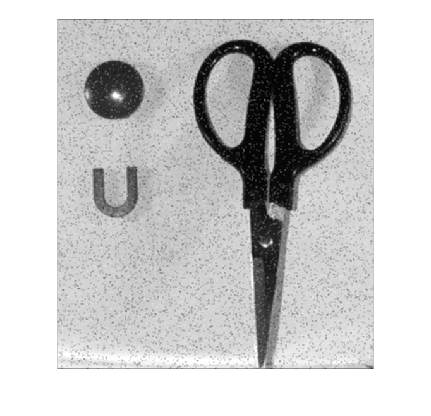



figure,imshow(image_low)

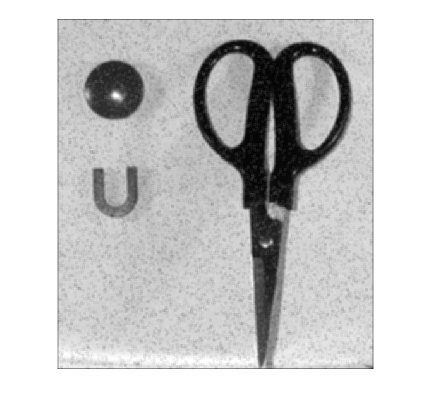

figure,imshow(image_low2)

%%遮罩越大雜訊變少 也相對有可能損失清晰度



image_3=imread("l5_2.bmp")

image_3 = 554×500 uint8 matrix
   202   201   201   201   202   202   204   204   204   205   203   202   202   201   202   201   200   198   198   199   200   200   200   199   198   200   201   201   201   197   196   197   200   199   199   199   199   202   202   199   201   201   201   200   198   195   195   195   198   198
   199   198   199   201   202   202   202   202   204   204   204   202   200   201   201   200   200   200   201   202   201   198   198   196   198   199   198   199   201   200   199   197   197   200   201   201   200   199   200   202   204   202   201   200   199   198   196   195   198   198
   198   198   198   200   202   202   202   202   204   203   202   200   199   196   198   200   201   200   201   202   202   200   198   198   199   198   199   201   201   201   200   199   199   200   200   200   200   197   198   199   200   199   200   199   198   198   196   196   199   197
   200   201   200   200   201   202   202   203   204   204   203

image_noisy=imnoise(image_3,"gaussian",0.06)

image_noisy = 554×500 uint8 matrix
   208   211   243   191   241   180   204   204   169   199   200   255   169   215   227   235   224   197   207   226   138   156   168   150   201   183   237   150   201   219   147   230   250   202   255   211   255   217   247   230   230   238   255   244   192   248   185   228   249   238
   215   207   224   175   199   255   225   237   194   214   226   186   237   183   207   205   204   179   230   214   180   247   161   212   156   219   178   201   245   219   238   184   220   255   255   211   180   239   209   202   255   243   166   202   199   199   182   217   254   214
   206   213   187   220   216   206   192   200   204   213   174   187   211   200   185   188   205   216   196   193   255   247   255   210   201   204   211   255   199   194   189   236   235   206   215   248   215   243   237   246   236   211   178   165   255   173   216   170   236   210
   205   254   186   162   253   214   211   199   147   205  

image_2_noisy=double(image_noisy)/255

image_2_noisy =     0.8157    0.8275    0.9529    0.7490    0.9451    0.7059    0.8000    0.8000    0.6627    0.7804    0.7843    1.0000    0.6627    0.8431    0.8902    0.9216    0.8784    0.7725    0.8118    0.8863    0.5412    0.6118    0.6588    0.5882    0.7882    0.7176    0.9294    0.5882    0.7882    0.8588    0.5765    0.9020    0.9804    0.7922    1.0000    0.8275    1.0000    0.8510    0.9686    0.9020    0.9020    0.9333    1.0000    0.9569    0.7529    0.9725    0.7255    0.8941    0.9765    0.9333
    0.8431    0.8118    0.8784    0.6863    0.7804    1.0000    0.8824    0.9294    0.7608    0.8392    0.8863    0.7294    0.9294    0.7176    0.8118    0.8039    0.8000    0.7020    0.9020    0.8392    0.7059    0.9686    0.6314    0.8314    0.6118    0.8588    0.6980    0.7882    0.9608    0.8588    0.9333    0.7216    0.8627    1.0000    1.0000    0.8275    0.7059    0.9373    0.8196    0.7922    1.0000    0.9529    0.6510    0.7922    0.7804    0.7804    0.7137    0.8510   

image_low=filter2(h,image_2_noisy)

image_low =     0.3664    0.5699    0.5451    0.5547    0.5407    0.5682    0.5686    0.5373    0.5303    0.5237    0.5577    0.5547    0.5425    0.5394    0.5542    0.5673    0.5420    0.5407    0.5460    0.5207    0.5059    0.4575    0.4767    0.4566    0.4885    0.5115    0.5089    0.5281    0.5381    0.5529    0.5390    0.5529    0.5843    0.6261    0.6052    0.5956    0.5721    0.5869    0.5856    0.5983    0.6092    0.6044    0.5874    0.5481    0.5595    0.5251    0.5486    0.5730    0.6100    0.5961
    0.5490    0.8340    0.8153    0.8261    0.8205    0.8357    0.8292    0.7969    0.7991    0.7813    0.8078    0.8039    0.8031    0.7991    0.8039    0.8192    0.8074    0.8096    0.8096    0.8013    0.8087    0.7874    0.7869    0.7468    0.7564    0.7800    0.8009    0.8179    0.8205    0.8065    0.8087    0.8405    0.8793    0.9120    0.8967    0.8911    0.8797    0.8898    0.9020    0.9115    0.9111    0.8767    0.8288    0.8087    0.8179    0.8057    0.7922    0.8440    0.8


image_med=medfilt2(image_noisy,[3 3])

image_med = 554×500 uint8 matrix
     0   208   191   191   180   199   204   194   194   194   199   186   183   183   205   205   197   197   197   180   156   156   156   156   156   178   178   178   201   201   184   184   202   220   211   211   211   209   209   209   230   230   202   192   199   185   185   185   217   214
   207   211   211   216   206   206   204   204   204   200   200   200   200   207   205   205   205   205   207   207   214   180   210   201   201   201   204   201   201   201   219   230   230   235   215   215   217   237   237   236   236   236   211   199   199   199   199   217   228   236
   206   207   207   199   214   214   211   200   204   205   213   211   200   207   205   205   205   205   209   209   214   214   212   210   212   204   211   201   219   212   219   235   235   235   248   215   215   215   223   223   211   211   193   199   199   216   216   236   224   235
   205   206   213   211   211   211   207   204   205   213   2

image_med2=medfilt2(image_noisy,[5 5])

image_med2 = 554×500 uint8 matrix
     0     0   191   187   187   191   192   192   192   186   174   183   183   185   185   185   188   193   180   179   161   156   156   156   161   156   178   183   178   184   189   189   189   206   206   206   211   209   209   211   202   178   178   173   173   173   182   182   185   209
     0   187   206   206   199   200   200   200   200   199   194   200   200   200   205   205   205   205   205   205   199   199   199   201   199   201   201   201   199   201   212   212   215   220   215   211   215   211   215   217   211   202   199   199   192   199   216   216   217   222
   194   206   211   211   211   207   206   206   205   204   205   209   208   207   208   207   207   209   214   209   209   212   208   208   201   204   201   204   201   215   219   219   230   235   235   215   223   217   230   230   230   230   226   211   204   204   226   224   224   224
   187   206   211   213   211   214   214   214   215   214   

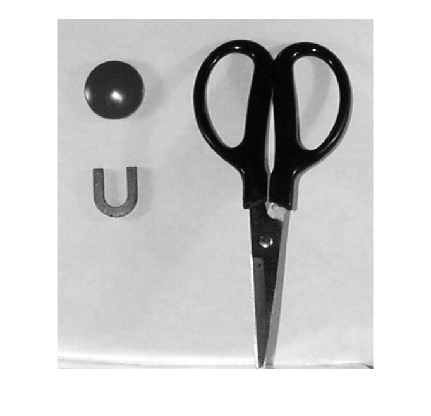



imshow(image_3)

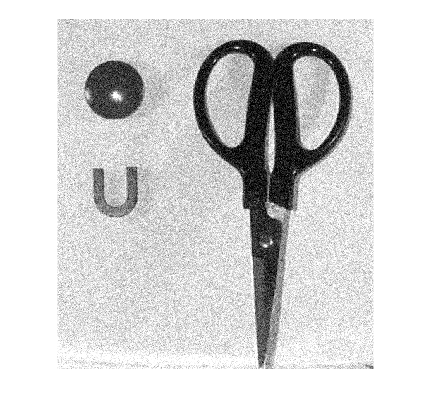

figure,imshow(image_noisy)

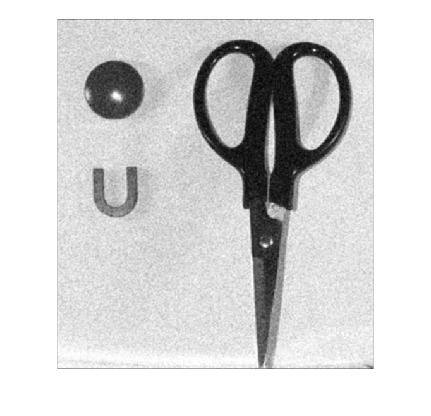

figure,imshow(image_low)

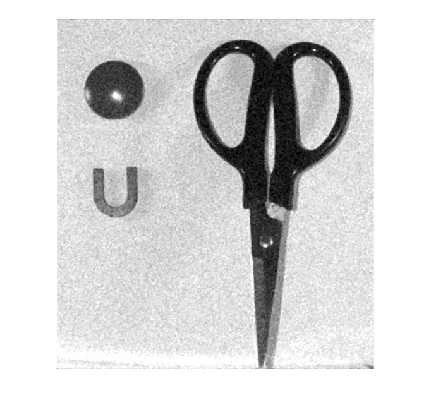

figure,imshow(image_med)


%%高斯雜訊顆粒感更重
